# **FORÅR 2018 EKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 SANDSYNLIGHED**

Et system er udviklet til at registrere om RFID tags er defekte. En undersøgelse viser, at givet et RFID tag ikke er defekt, er sandsynligheden for, at systemet registrerer, at det ikke er defekt lig med 0.4. Givet et RFID tag er defekt, er sandsynligheden for, at systemet registreret, at det er defekt lig med 0.999. Det vides, at 1 ud af 100 RFID tags er defekte.

A : RFID DEFEKT 

B : REGISTRER DEFEKT


$$P\left(A\right)=\frac{1}{100}$$



$$P\left(\overline{B} |\overline{A} \right)=0\ldotp 4$$



$$P\left(B|A\right)=0\ldotp 999$$


A = 1/100;
NotBGivenNotA = 0.4;
BGivenA = 0.999;

## 1.1 IKKE DEFEKT

For at bestemme sandsynligheden for at RFID tag ikke er defekt anvendes, at


$$P\left(A\right)=1-P\left(\overline{A} \right)$$


NotA = 1 - A

NotA = 0.9900

Sandsynligheden er dermed bestemt til at være 0.99.

## 1.2 TOTALE SANDSYNLIGHED

For at bestemme den totale sandsynligheden for at systemet registerer et RFID tag som er defekt anvendes, at


$$P\left(B\right)=P\left(B|A\right)\cdot P\left(A\right)+P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)$$



$$P\left(B|\overline{A} \right)=1-P\left(\overline{B} |\overline{A} \right)$$


BGivenNotA = 1 - NotBGivenNotA;

B = BGivenA * A + BGivenNotA * NotA

B = 0.6040

Sandsynligheden er dermed bestemt til at være 0.6040 altså 60.40%.

## 1.3 BETINGET SANDSYNLIGHED

For at bestemme hvad sandsynligheden for at et RFID tag er defekt givet at det er registreret som defekt anvendes, at


$$P\left(A|B\right)=\frac{P\left(B|A\right)\cdot P\left(A\right)}{P\left(B\right)}$$


AGivenB = (BGivenA * A) / B

AGivenB = 0.0165

Sandsynligheden er dermed bestemt til at være 0.0165 altså 1.65%.

## 1.4 BETINGER SANDSYNLIGHED 2

For at bestemme hvad sandsynligheden for at et RFID tag ikke er defekt givet at det er registreret som defekt anvendes, at


$$P\left(\overline{A} |B\right)=\frac{P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)}{P\left(B\right)}$$


%NoAGivenB = 1 - AGivenB
NotAGivenB = (BGivenNotA * NotA) / B

NotAGivenB = 0.9835

Sandsynligen er dermed bestemt til at være 0.9835 altså 98.35%.

# **2 STOKASTISKE VARIABLE**

En tæthedsfunktion for en stokastisk variabel er defineret til at være 

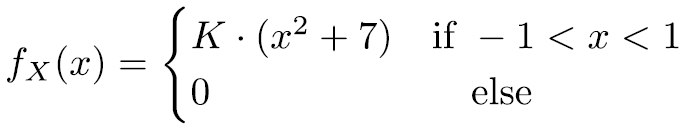

## 2.1 GYLDIG TÆTHEDSFUNKTION

For en gyldig tæthedsfunktion gælder, at


$$\int_{-\infty }^{\infty } f_X \left(x\right)\mathrm{dx}=1$$


Hvor $k$ kan isoleres og beregnes som følgende i matlab.

syms fx(x) k
fx(x) = piecewise(-1<x<1, k*(x^2 + 7), 0);
k = solve(int(fx(x), -inf, inf) == 1, k)

$$k = \frac{3}{44}$$

Dermed er $k$ bestemt til at være lig med $\frac{3}{44}$ for at $f_X \left(x\right)$er en gyldig tæthedsfunktion.

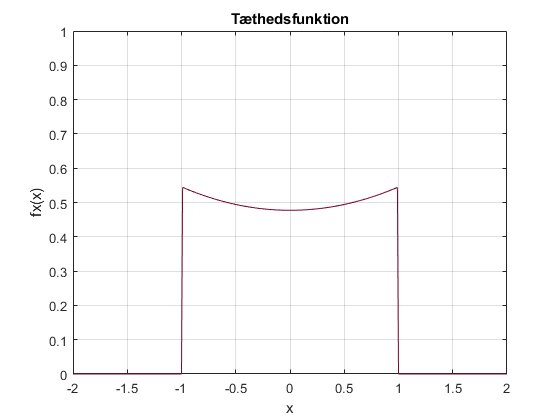

syms fx(x) 
fx(x) = piecewise(-1<x<1, (3/44)*(x^2 + 7), 0);
x = -2:0.01:2;

figure(1)
plot(x, fx(x), 'Color', Color.DeepCleret);
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
axis([-2, 2, 0, 1]);

## 2.2 MIDDELVÆRDI

For at bestemme middelværiden anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$



$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$


syms xfx(x) 
xfx(x) = piecewise(-1<x<1, x*((3/44)*(x^2 + 7)), 0);

MeanValue = int(xfx(x), -inf, inf)

$$MeanValue = 0$$

Dermed middelværiden bestemt til at være 0.

## 2.3 VARIANS

For at bestemme standard afvigelsen benyttes, at


$$\mathrm{Var}\left(x\right)=\sigma^2 =\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$



$$\sigma =\sqrt{\sigma^2 }$$


syms xfx(x) 
xfx(x) = piecewise(-1<x<1, x^2*((3/44)*(x^2 + 7)), 0);

MeanSquareValue = int(xfx(x), -inf, inf);

Variance = MeanSquareValue - MeanValue^2;
StandardDeviation = sqrt(Variance)

$$StandardDeviation = \frac{\sqrt{19}\,\sqrt{55}}{55}$$

(sqrt(19)*sqrt(55)) / 55

ans = 0.5878

Standard afvigelsen er dermed bestemt til at være 0.5878.

## 2.4 FORDELINGSFUNKTION

For at finde fordelingsfunktionen anvendes, at


$$F_X \left(x\right)=\int_{-\infty }^x f_X \left(x\right)\mathrm{dx}$$


syms fx(x) k
fx(x) = piecewise(-1<x<1, (3/44)*(x^2 + 7), 0);

int(fx(x), -inf, x)

$$ans = \left\{ \begin{array}{cl} 1 & \text{ if }1\leq x\\ 0 & \text{ if }x\leq -1\\ \frac{x^{3}}{44}+\frac{21\,x}{44}+\frac{1}{2} & \text{ if }x\in \left(-1,1\right] \end{array}\right.$$

# **3 STOKASTISKE PROCESSER**

En kontinuert stokastisk process er givet ved


$$y\left(t\right)=x\left(t\right)+w$$


hvor $x\left(t\right)\sim N\left(0,t^2 \right)$og $w\sim N\left(3,1\right)$. x og w er uafhængige.